% Task 4.
e = exp(1);
f = @(x) exp(x)/(e-1);
%u = rand;
F_inv = @(u) log((e-1)*u+1);
u_s = [0.76,0.74,0.39,0.66,0.17]
F_inv(u_s)

% Task 4 + acceptance rejection.
g = @(x) 1;
G_inv = @(u) u;
% Determine c as the maximum of max(f/g)=max(f)=e/(e-1)
c = e/(e-1);
N = 100;
X = zeros(1,N);
for i = 1:N
    while true
        u = rand;
        y = G_inv(u);
        u = rand;
        if c*g(y)*u<f(y)
            x=y;
            break
        end
    end
    X(i)=x;

end
histogram(X,"Normalization","pdf")
hold on;
t = [0:0.01:1]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


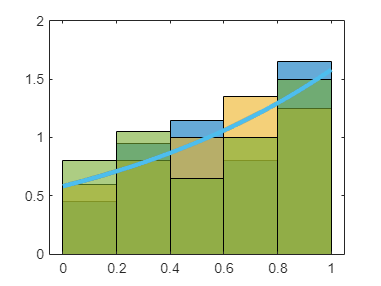

plot(t,f(t),'LineWidth',3)
hold off